# Title & Documentation

% Image and Facial Recognition
% Copyright 2014 The MathWorks, Inc.

## Step 1 (Loading Image Info)

% Load Image
faceDatabase = imageSet('FaceDatabaseATT','recursive');

## Step 2 (Displaying Image Info in preset format)

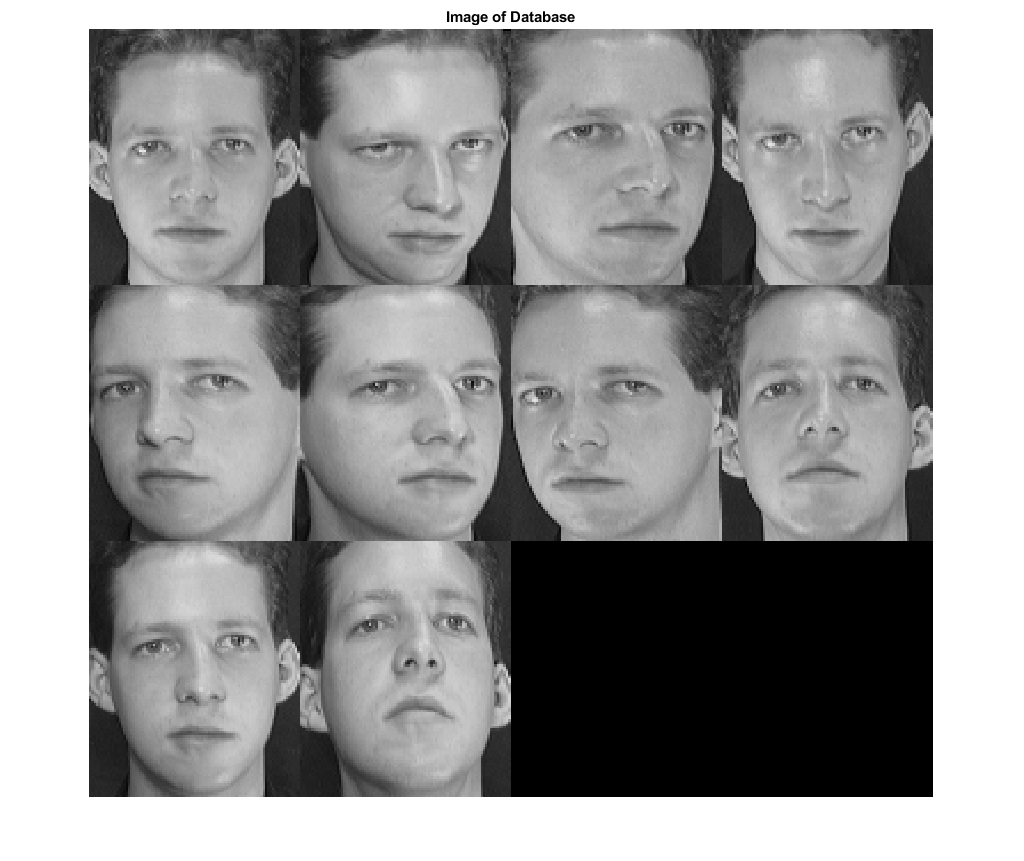

% Displaying Montage
figure;
montage(faceDatabase(1).ImageLocation);
title('Image of Database');

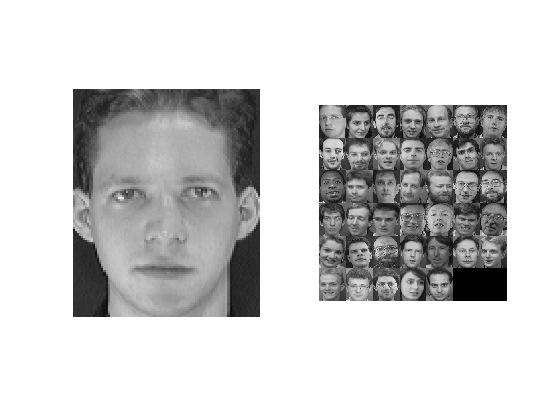


% Displaying Query Image and Database Side-Side
personToQuery = 1;
galleryImage = read(faceDatabase(personToQuery),1);
figure;
for i=1:size(faceDatabase,2)
imageList(i) = faceDatabase(i).ImageLocation(5);
end
subplot(1,2,1);imshow(galleryImage);
subplot(1,2,2);montage(imageList);

diff = zeros(1,9);

## Step 3 (Data Partition)

% Split Database into Training & Test Sets
[training,test] = partition(faceDatabase,[0.8 0.2]);

## Step 4 (Using HoG for Data analysis)

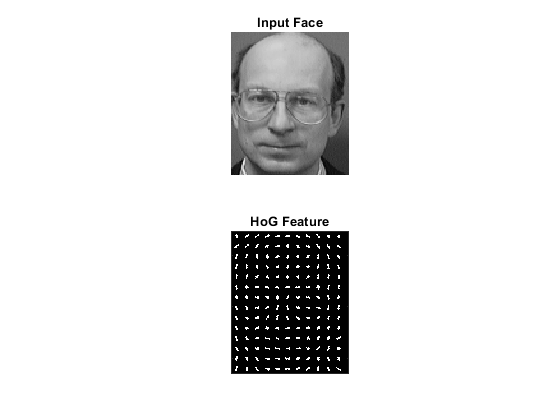

% Extract and display Histogram of Oriented Gradient Features for single face 
person = 5;
[hogFeature, visualization]= ...
    extractHOGFeatures(read(training(person),1));
figure;
subplot(2,1,1);imshow(read(training(person),1));title('Input Face');
subplot(2,1,2);plot(visualization);title('HoG Feature');


% Extract HOG Features for training set 
trainingFeatures = zeros(size(training,2)*training(1).Count,4680);
featureCount = 1;
for i=1:size(training,2)
    for j = 1:training(i).Count
        trainingFeatures(featureCount,:) = extractHOGFeatures(read(training(i),j));
        trainingLabel{featureCount} = training(i).Description;    
        featureCount = featureCount + 1;
    end
    personIndex{i} = training(i).Description;
end

## Step 5 (Creating Classifiers for Method)

% Create 40 class classifier using fitcecoc 
faceClassifier = fitcecoc(trainingFeatures,trainingLabel);

## Step 6 (Testing)

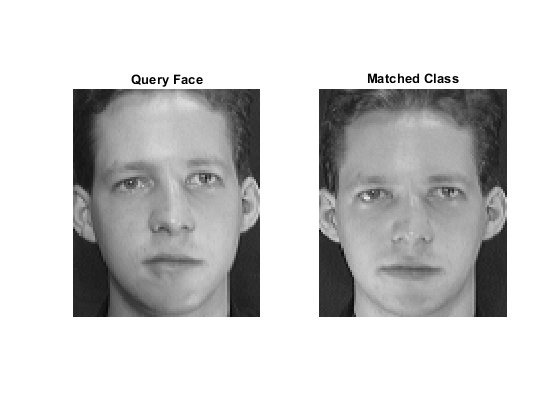

% Test Images from Test Set 
person = 1;
queryImage = read(test(person),1);
queryFeatures = extractHOGFeatures(queryImage);
personLabel = predict(faceClassifier,queryFeatures);
% Map back to training set to find identity 
booleanIndex = strcmp(personLabel, personIndex);
integerIndex = find(booleanIndex);
subplot(1,2,1);imshow(queryImage);title('Query Face');
subplot(1,2,2);imshow(read(training(integerIndex),1));title('Matched Class');

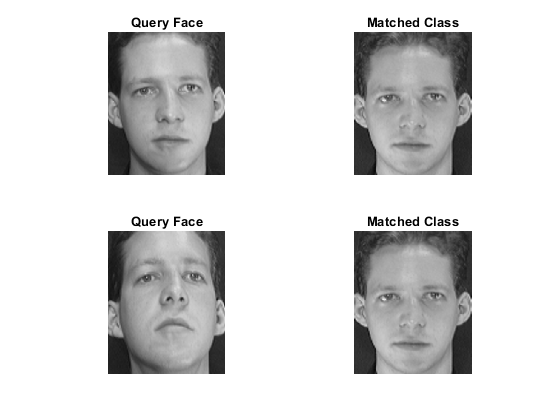

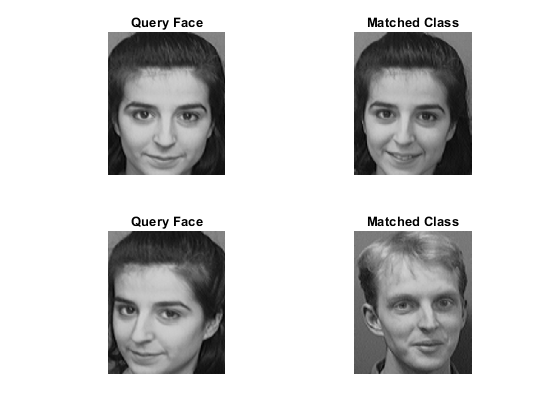

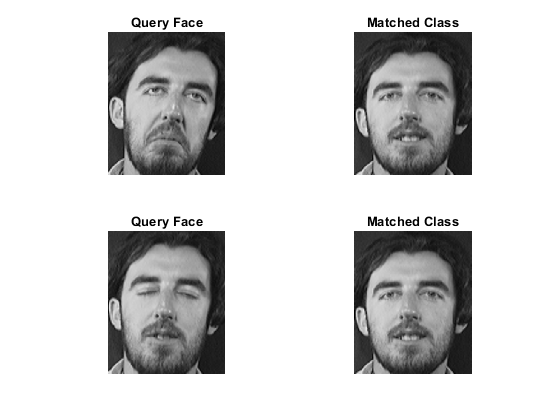

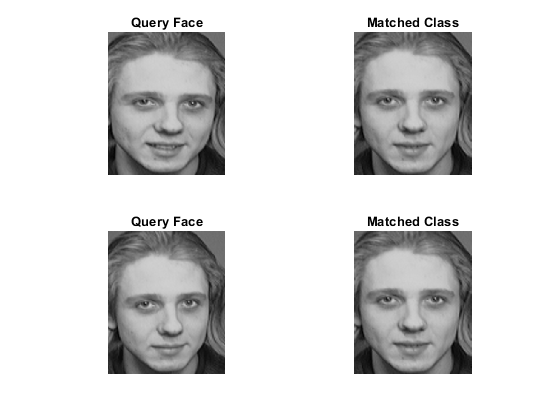

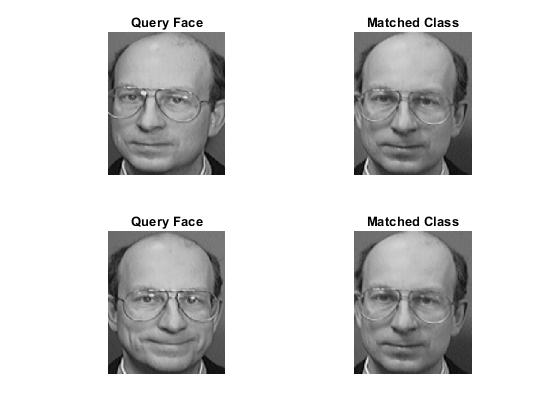


% Test First 5 People from Test Set
figure;
figureNum = 1;
for person=1:5
    for j = 1:test(person).Count
        queryImage = read(test(person),j);
        queryFeatures = extractHOGFeatures(queryImage);
        personLabel = predict(faceClassifier,queryFeatures);
        % Map back to training set to find identity
        booleanIndex = strcmp(personLabel, personIndex);
        integerIndex = find(booleanIndex);
        subplot(2,2,figureNum);imshow(imresize(queryImage,3));title('Query Face');
        subplot(2,2,figureNum+1);imshow(imresize(read(training(integerIndex),1),3));title('Matched Class');
        figureNum = figureNum+2;
        
    end
    figure;
    figureNum = 1;

end